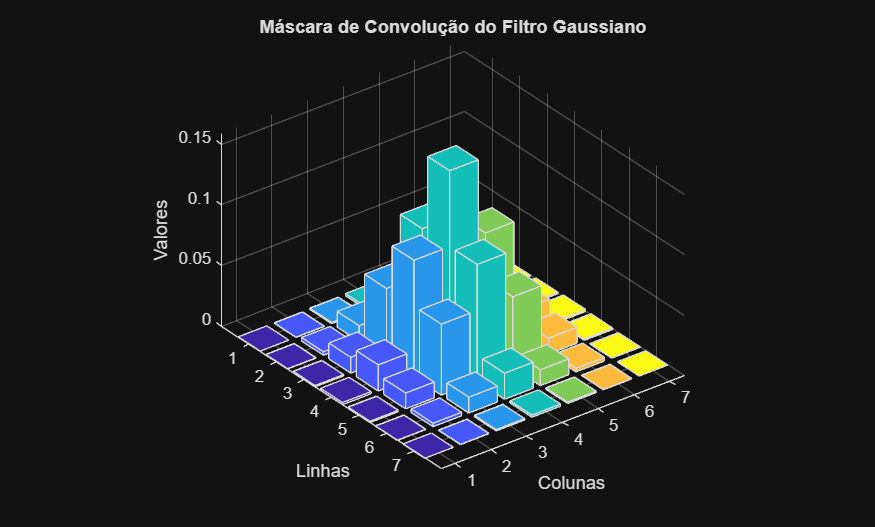

clear all;
clc;

img = imread("einstein.gif");
[nl, nc] = size(img);

%parametros do spatial kernel
sigma_s = 1;
Janela_s = 2 * ceil(3 * sigma_s) + 1;

%Criação do spatial kernel

Masc_Gaussiana = fspecial('gaussian', [Janela_s, Janela_s], sigma_s);
figure;%Verificar se a mascara ficou correta
bar3(Masc_Gaussiana);
title('Máscara de Convolução do Filtro Gaussiano');
xlabel('Colunas');
ylabel('Linhas');
zlabel('Valores');

%parametros do range kernel
sigma_r = 0.05;
Janela_r =  Janela_s;

% Range_Gaussiana = fspecial('gaussian', [Janela_s, Janela_s], sigma_r);


img_bi = zeros(nl,nc);

for i = 1:nl
    for j = 1:nc
        % A diferença é calculada em relação aos vizinhos
        if i <= floor(Janela_r/2) || j <= floor(Janela_r/2) || i > (nl - floor(Janela_r/2)) || j > (nc - floor(Janela_r/2))

            img_bi(i,j) = img(i,j);

        else

            Range_kernel = zeros(Janela_r,Janela_r);
            for x = -floor(Janela_r/2):floor(Janela_r/2)
                for y = -floor(Janela_r/2):floor(Janela_r/2)
                    diff = double(img(i + x, j + y) - img(i, j));
                    Range_kernel(x+ceil(Janela_r/2),y+ceil(Janela_r/2)) =  (1 / (2 * pi * sigma_r^2)) * exp(-(diff) / (2 * sigma_r^2));
                end
            end
            
            Range_kernel = Range_kernel*Masc_Gaussiana;
            Range_kernel = Range_kernel/(sum(Range_kernel(:)));
            Range_kernel = rot90(Range_kernel, 2);
            region = img(i-floor(Janela_r/2):i+floor(Janela_r/2), j - floor(Janela_r/2):j + floor(Janela_r/2));
            region = double(region);
            conv = sum(sum(region.*Range_kernel));
            img_bi(i,j) = conv;

        end
    end
end
img_bi = uint8(img_bi);


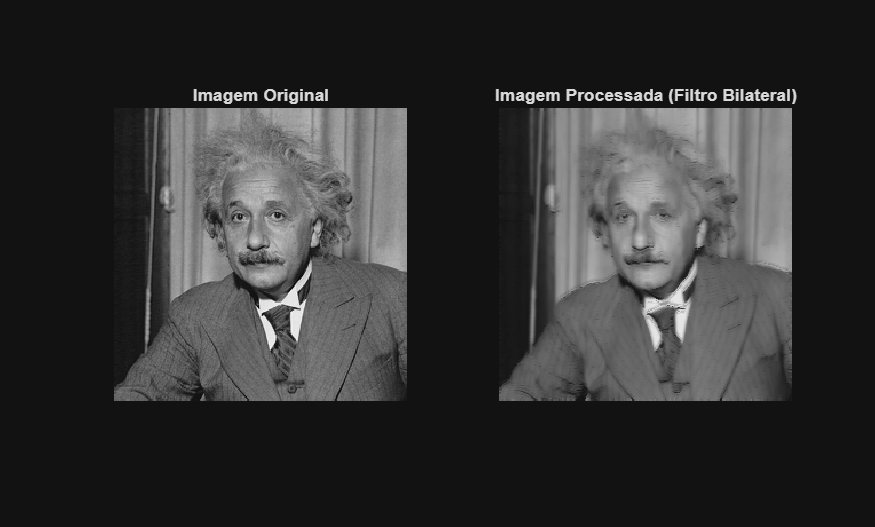

figure;
subplot(1, 2, 1);  % Imagem original
imshow(img);
title('Imagem Original');

subplot(1, 2, 2);  % Imagem processada (filtrada)
imshow(img_bi);
title('Imagem Processada (Filtro Bilateral)');